a = 4; b = 4;

T = 20; dt = 0.1;
t = -T/2 : dt : T/2;

func = a - abs(t .* (a / b));
func(abs(t) > b) = 0;

W = 20; dw = 0.1;
w = -W/2 : dw : W/2;

func_fourier = @(w) ((a*b/sqrt(2*pi)) * sinc((b*w) / 2));

fourier_domain = arrayfun(func_fourier, w);

disp([dot(fourier_domain, fourier_domain) * dw, dot(func, func) * dt]);

   20.2686   42.6800



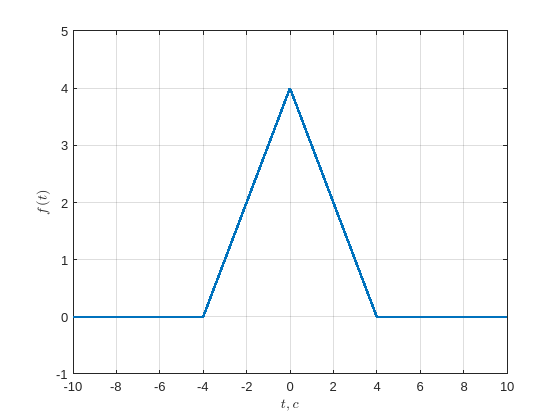

figure;
plot(t, func, 'LineWidth', 2);
ylim([-1, a + 1]);
ylabel({"$f(t)$"}, 'Interpreter', 'latex');
xlabel({"$t, c$"}, 'Interpreter', 'latex');
grid on;


% saveas(gcf, './plots/task_1/1_2_2.png');

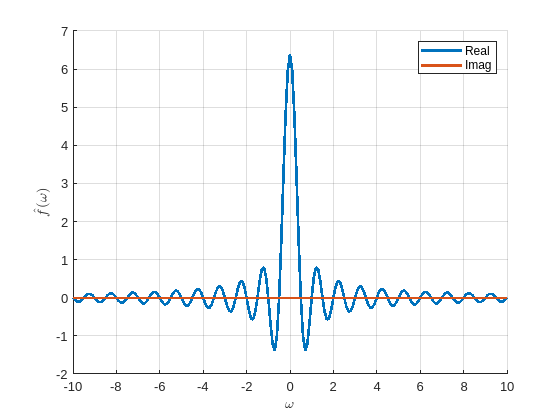

figure;
hold on;
plot(w, real(fourier_domain), 'LineWidth', 2);
plot(w, imag(fourier_domain), 'LineWidth', 2);
hold off;
ylabel({"$\hat{f}(\omega)$"}, 'Interpreter', 'latex');
xlabel({"$\omega$"}, 'Interpreter', 'latex');
legend({"Real", "Imag"});
grid on;


% saveas(gcf, './plots/task_1/1_1_4.png');